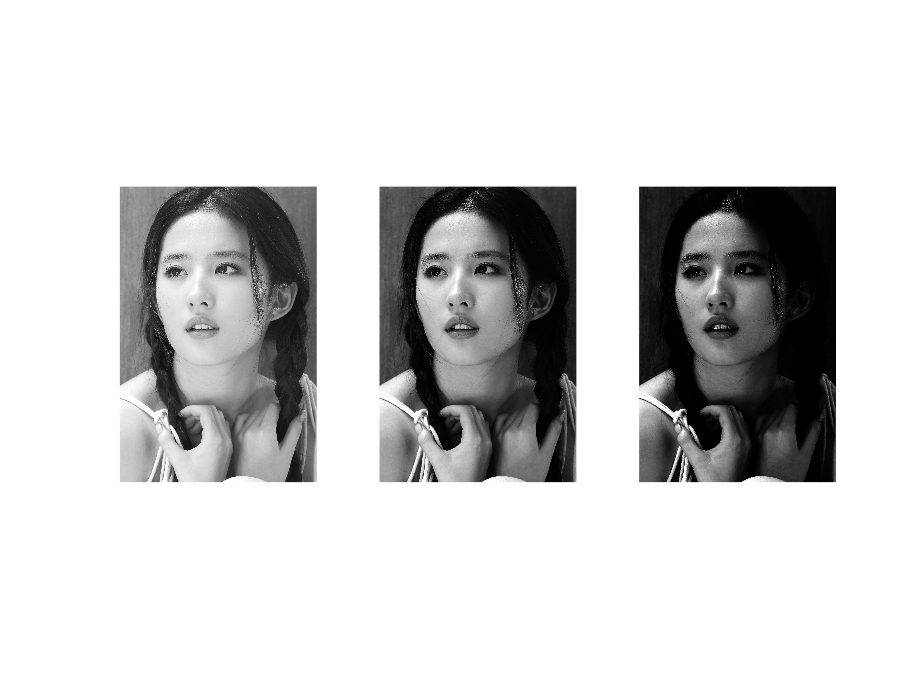

img = rgb2gray(imread('lyf.jpg'));
subplot(1,3,1);
imshow(img)
f = @(x)x.^2;
g = @(x)x.^4;
img2 = im2uint8(f(mat2gray(img))); %生成一幅比较黑的图像，后续要用
img3 = im2uint8(g(mat2gray(img)));
subplot(1,3,2);
imshow(img2);
subplot(1,3,3);
imshow(img3);

# 绘制灰度直方图

一，imhist(f,b)，b为组数，默认为256

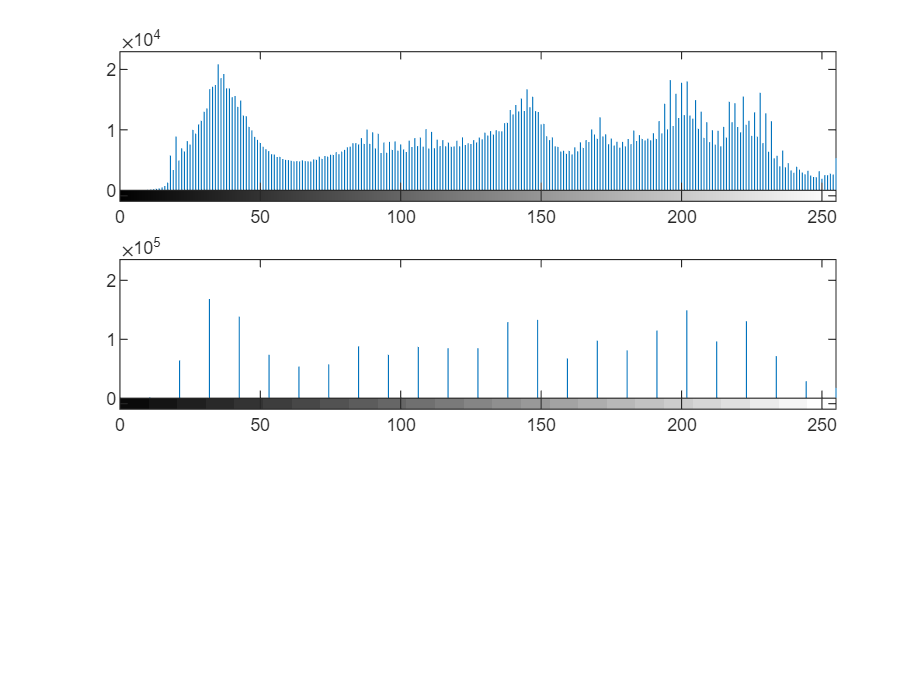

figure(1)
clf;
subplot(3,1,1); imhist(img);
subplot(3,1,2); imhist(img,25)

二，bar

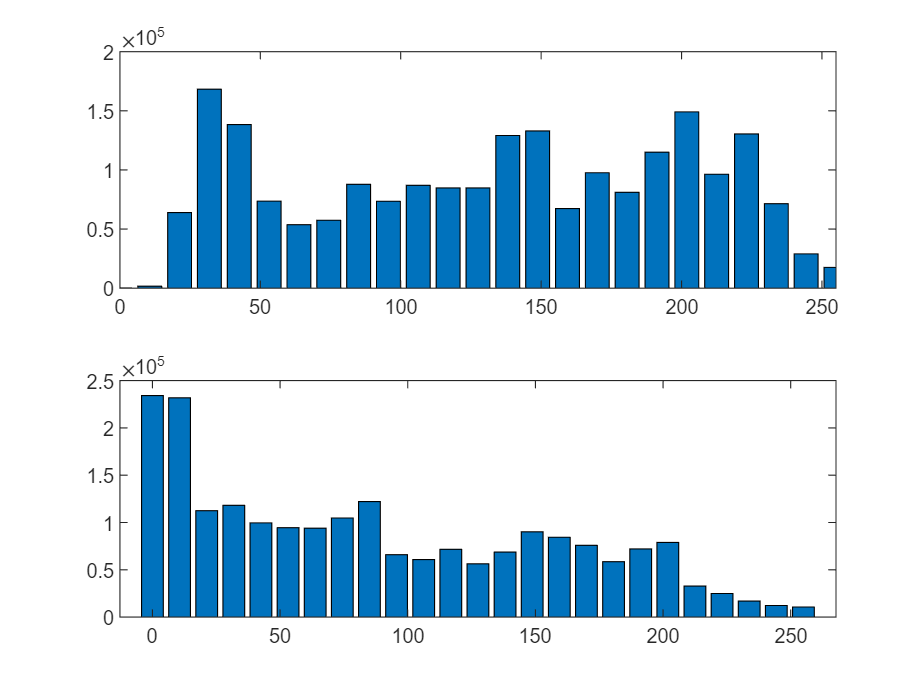

h = imhist(img,25);
x = linspace(0,255,25);
figure(2)
clf
subplot(2,1,1);
bar(x,h)
axis([0,255,0,200000]);
h = imhist(img2,25);
subplot(2,1,2);
bar(x,h)

上述bar已定义为一个函数，graybar

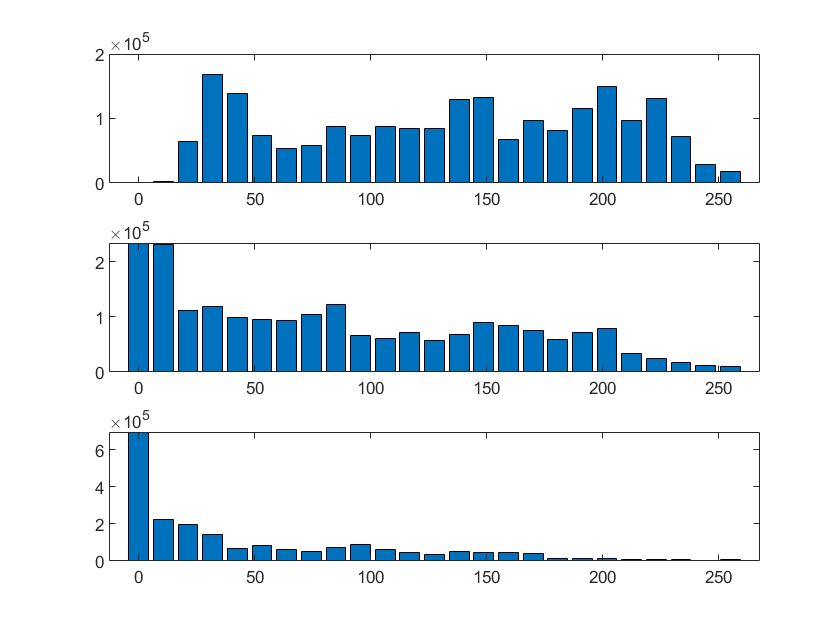

graybar(img,img2,img3)

# 直方图均衡化

histeq函数

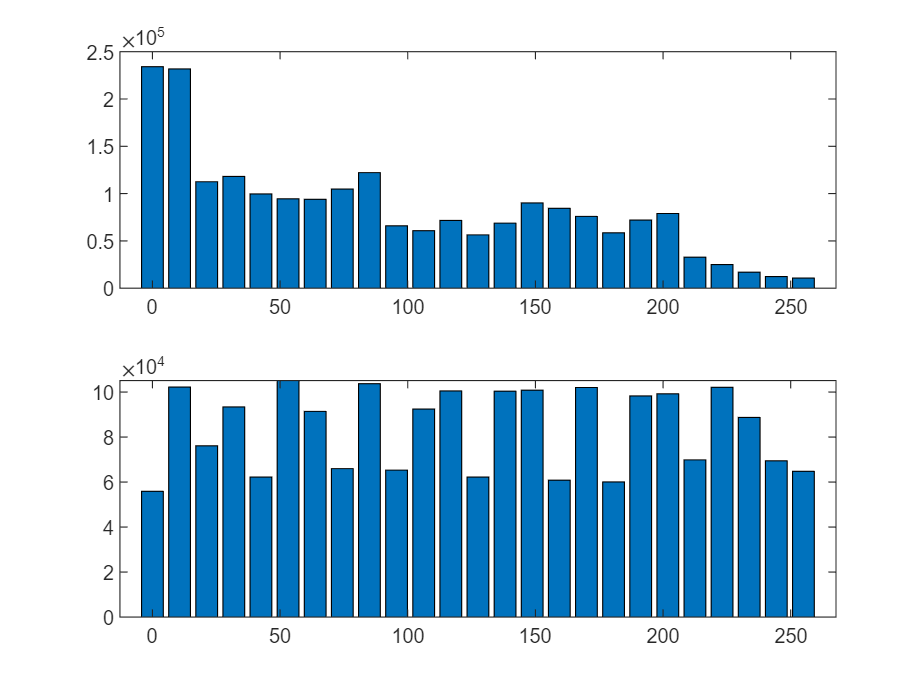

img_eq = histeq(img2); 
graybar(img2,img_eq)

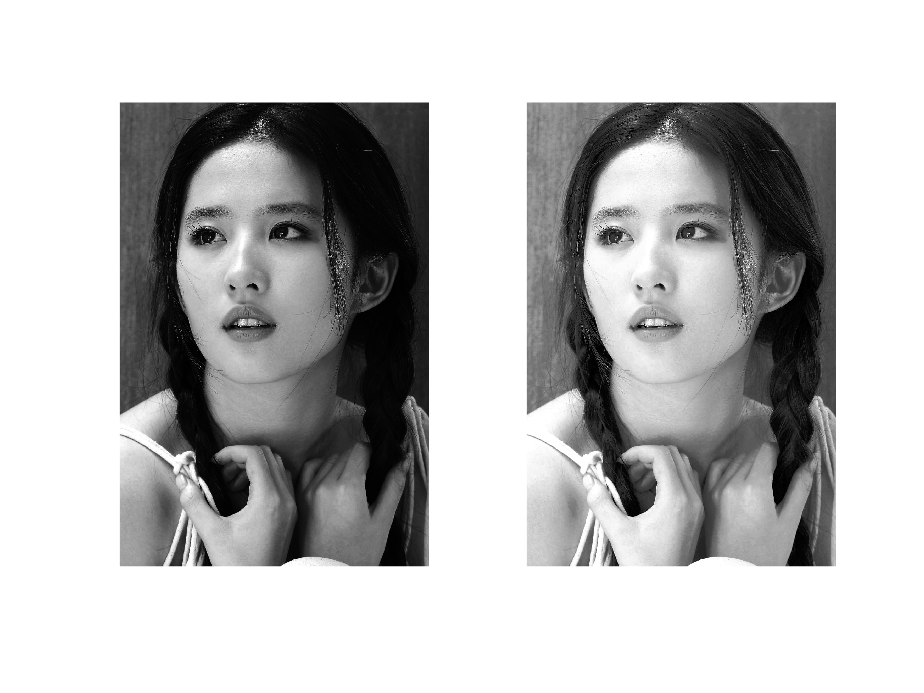

figure(3)
subplot(1,2,1); imshow(img2)
subplot(1,2,2); imshow(img_eq)

# 直方图匹配

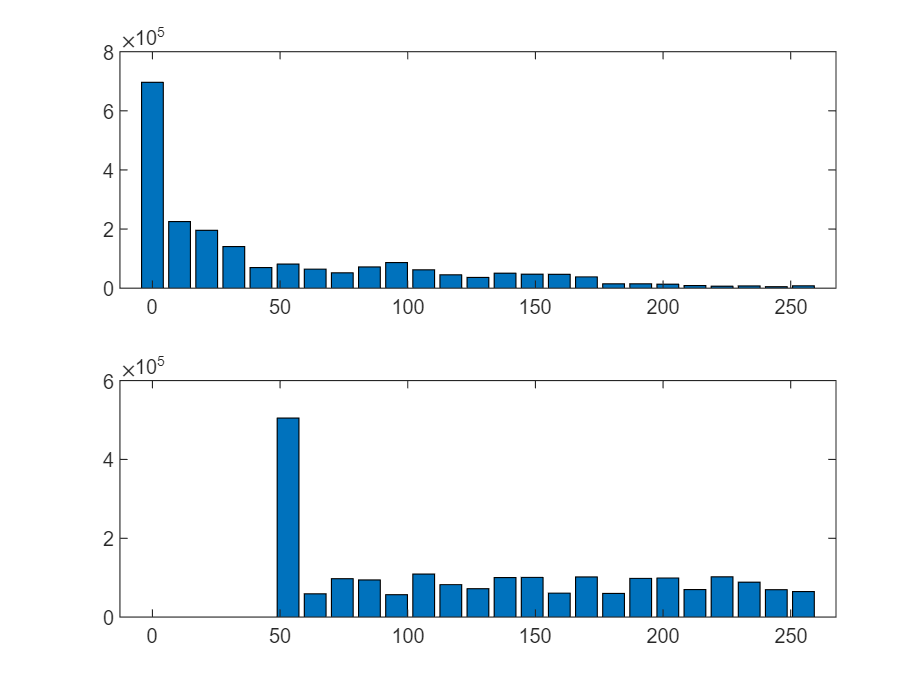

img_eq3 = histeq(img3); 
graybar(img3,img_eq3)

不难看出，img3均衡化并不理想。应用**直方图匹配**

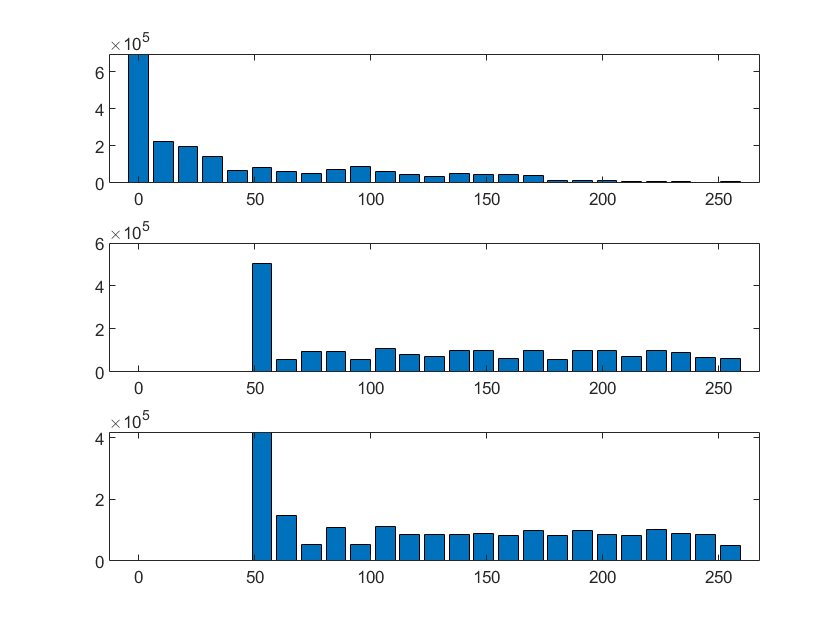

x = linspace(0,256,1000);
object = log(256+x);
%object = -(x-256).^2 + 256^2;
img_match = histeq(img3,object);
graybar(img3,img_eq3,img_match);

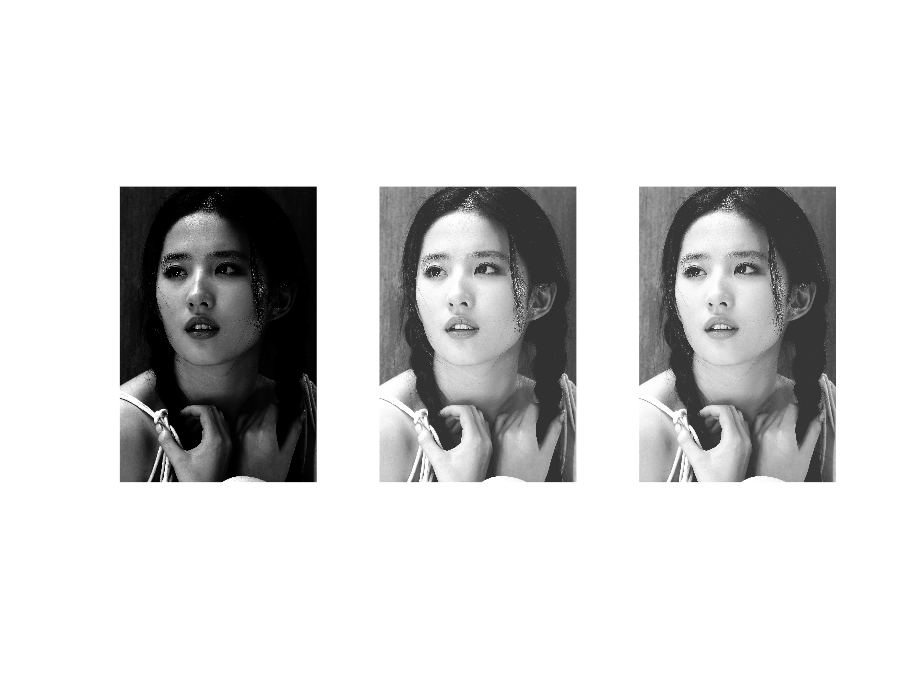

figure(4)
clf;
subplot(1,3,1); imshow(img3);
subplot(1,3,2); imshow(img_eq3);
subplot(1,3,3); imshow(img_match);

自适应调整直方图函数：`adapthisteq`

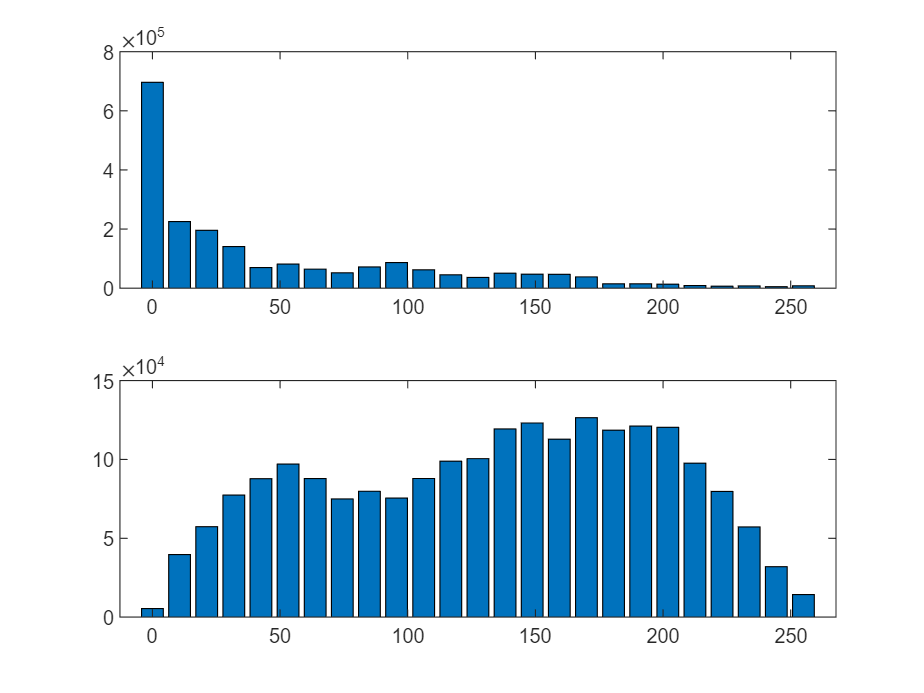

img_adapt = adapthisteq(img);
graybar(img3,img_adapt);

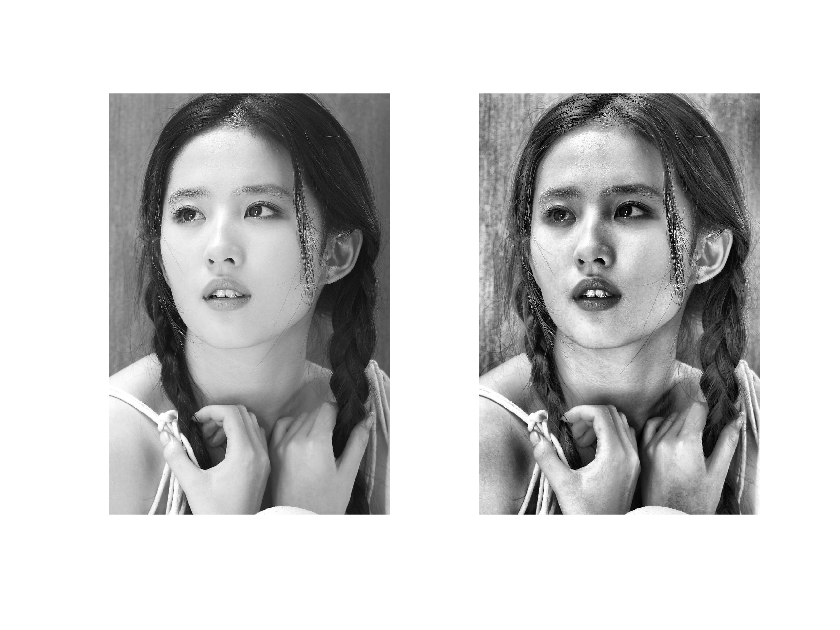

figure(5)
subplot(1,2,1); imshow(img);
subplot(1,2,2); imshow(img_adapt);

定义一个用bar画灰度图的函数

function g = graybar(img,varargin)
    num = length(varargin);
    h = imhist(img,25);
    x = linspace(0,255,25);
    clf;
    subplot(num+1,1,1);
    bar(x,h)
    for i = 1:num
        h = imhist(varargin{i},25);
        x = linspace(0,255,25);
        subplot(num+1,1,i+1);
        bar(x,h) 
    end
end

